# Example: Quality Control Module 

The following example runs a simple quality control analysis on wave elevation data. The data file used in this example is stored in the [\MHKiT\examples\data](https://github.com/MHKiT-Code-Hub/MHKiT-Python/tree/master/examples/data) directory.

## Import Data

Load the data into a table. The data includes several issues, including timestamps that are out of order, corrupt data with values of -999, data outside expected range, and stagant data. The first 5 rows of data are shown below, along with a plot.

data=readtable('../examples/data/wave_elevation_data.csv');
disp(data)

     Time     probe1    probe2    probe3
    ______    ______    ______    ______

        10     24.48     28.27      1.3 
    10.002     34.48     40.27     -8.7 
    10.004     30.48     38.27    -13.7 
    10.006     12.48     24.27    -32.7 
    10.008     13.48     22.27    -21.7 
     10.01      7.48     15.27    -13.7 
    10.012      4.48     13.27    -19.7 
    10.014     -9.52     -0.73    -11.7 
    10.016      8.48     19.27    -16.7 
    10.018     -4.52      8.27    -34.7 
     10.02     16.48     27.27      5.3 
    10.022    -13.52     -0.73    -36.7 
    10.024    -13.52      0.27    -39.7 
    10.026    -15.52     -3.73    -32.7 
    10.028    -22.53    -17.73    -23.7 
     10.03    -22.52    -16.73     16.3 
    10.032      -999    -23.73      1.3 
    10.034      -999    -16.73     11.3 
    10.036      -999    -24.73     13.3 
  

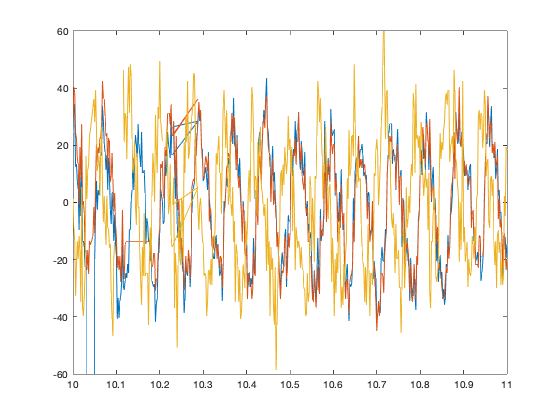

plot(data.Time,[data.probe1,data.probe2,data.probe3]);
ylim([-60 60]);

The MHKiT-Matlab QC module utilizes structures. WE need to convert the table of data into a structure. 

datast.time=data.Time;
datast.values = 
